Maticové funkce

Úkol 1 Maticová funkce pro malou matici.

Náhodná testovací funkce

A = rand(5)

A =     0.8687    0.4314    0.1361    0.8530    0.0760
    0.0844    0.9106    0.8693    0.6221    0.2399
    0.3998    0.1818    0.5797    0.3510    0.1233
    0.2599    0.2638    0.5499    0.5132    0.1839
    0.8001    0.1455    0.1450    0.4018    0.2400


Pomocí vestavěné funkce `funm(A, @fun)` zjistíme referenční řešení pro $\sin(A)$

S = funm(A, @sin)

S =     0.5765    0.1506   -0.2074    0.4602   -0.0360
   -0.2187    0.6098    0.4609    0.2232    0.1121
    0.2015    0.0138    0.3720    0.1026    0.0553
    0.0521    0.0852    0.3208    0.2538    0.1094
    0.5684   -0.0547   -0.0781    0.1037    0.1637


 Aproximace pomocí Taylorova polynomu/řady $\sin(A) \approx A - \frac{1}{3!} A^3 + \frac{1}{5!}  A^5$

Spočteme jeden člen.

norm(A - S)

ans = 1.2592

Spočteme dva členy lepší výsledek.

B = A - (1/factorial(3)) * A^3;
norm(B - S)

ans = 0.2942

Zvyšujeme počet členů řady a sledujeme konvergenci

Spočteme pro tři členy

C = A - (1/factorial(3)) * A^3  + 1/factorial(5) * A^5;
norm (C - S)

ans = 0.0305

Spočteme pro cca 50 členů Taylorova rozvoje.

n = 50;
h = zeros(1, n);

B = A;
for i = 1:n
    B = B - ((-1)^i) / factorial(2 * i + 1) * A^(2 * i + 1);
    h(i) = norm(B - S);
end

Vykreslíme graf

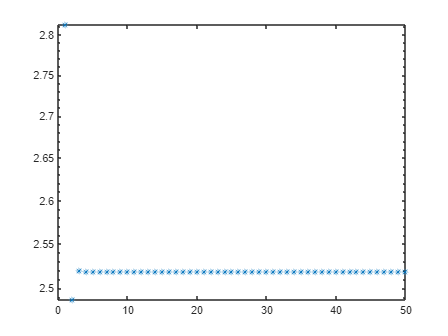

semilogy(h, '*')